# DSZOB, cvičenie 5.

## **Zadanie:**

## **Úloha 1 Windowing**

Vygenerujte signál pre časový úsek 0-1s:

- Zložený signál obsahujúci 5 rôznych frekvencií a so vzorkovacou frekvenciou 44.1kHz. (vznikne aditívne so zvolenými násobnými koeficientami)

Vypočítajte Fourierovo spektrum (funkcia fft) zo selektovaného kratšieho časového úseku tohto signálu nasledujúcimi spôsobmi:

- Hammingovo okienko (windowing)

- Pravouhlé okienko (windowing)

Aký bol rozdiel vo výslednej Fourierovej transformácii pri použití Hammingovho a Pravouhlého okienka?

% Riesenie / Solution
% Vygenerujte zložený signál obsahujúci 5 rôznych frekvencií a so vzorkovacou frekvenciou 44.1kHz.
fs = 44100;
x_0 = 0:1/fs:1;
signal1 = sin(2*pi*440*x_0) * 1;
signal2 = sin(2*pi*929*x_0) * 0.8;
signal3 = sin(2*pi*324*x_0) * 0.4;
signal4 = sin(2*pi*567*x_0) * 1;
signal5 = sin(2*pi*823*x_0) * 0.2;

sumSignal = signal1 + signal2 + signal3 + signal4 + signal5;
display("Lenght of whole signal: " + length(sumSignal))

    "Lenght of whole signal: 44101"



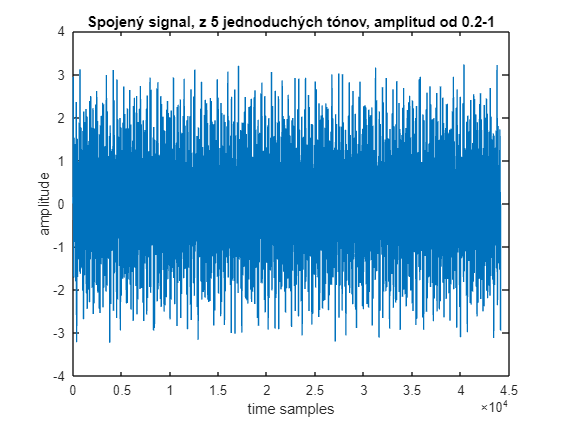

plot(sumSignal);
title("Spojený signal, z 5 jednoduchých tónov, amplitud od 0.2-1")
xlabel("time samples")
ylabel("amplitude")

% Príprava okienok
hammingWindow = hamming(512);
zeroPadding = zeros(1,128);
onePadding = ones(1,256);
rightRectWindow = [zeroPadding, onePadding, zeroPadding];
rightRectWindow = rightRectWindow;

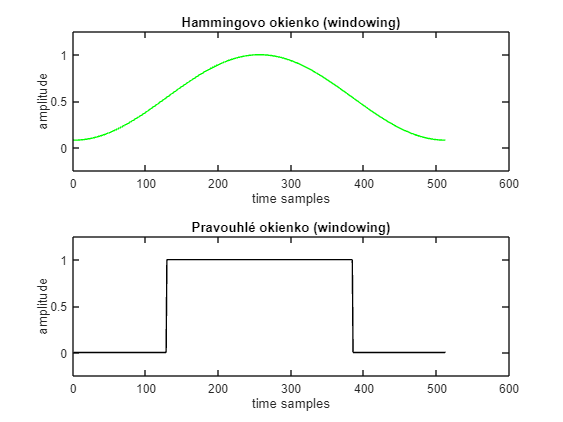


figure
tiledlayout(2,1)
nexttile
plot(hammingWindow, Color="green")
title('Hammingovo okienko (windowing)')
xlabel("time samples")
ylabel("amplitude")
ylim([-0.25, 1.25])
nexttile
plot(rightRectWindow, Color="black")
title('Pravouhlé okienko (windowing)')
xlabel("time samples")
ylabel("amplitude")
ylim([-0.25, 1.25])

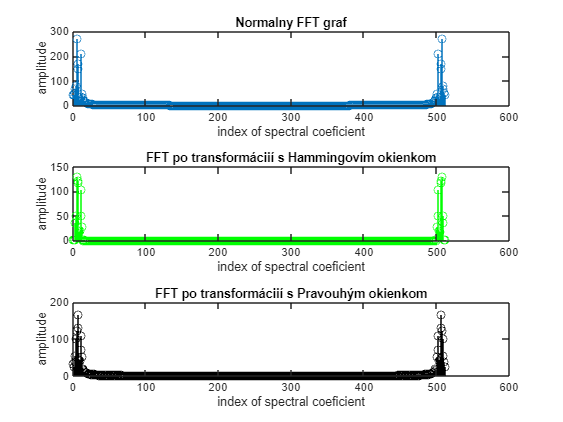


% Vypočítajte Fourierovo spektrum (funkcia fft) zo selektovaného kratšieho časového úseku tohto signálu nasledujúcimi spôsobmi
    % - selektovaného kratšieho časového úseku tohto signálu
    shortSumSig = sumSignal(1:512);
    nFFT = fft(shortSumSig);
    hamFFT = fft(shortSumSig.*hammingWindow');  %---pre násobenie prvkov vectoroj, je potrebné abe oba vectory boli rovnakého typu, inak výjde matica
    rectFFT = fft(shortSumSig.*rightRectWindow);
figure
tiledlayout(3,1)
nexttile
stem(abs(nFFT))
title('Normalny FFT graf')
xlabel("index of spectral coeficient")
ylabel("amplitude")
nexttile
stem(abs(hamFFT), Color="green")
title('FFT po transformáciií s Hammingovím okienkom')
xlabel("index of spectral coeficient")
ylabel("amplitude")
nexttile
stem(abs(rectFFT), Color="black")
title('FFT po transformáciií s Pravouhým okienkom')
xlabel("index of spectral coeficient")
ylabel("amplitude")

%Aký bol rozdiel vo výslednej Fourierovej transformácii pri použití Hammingovho a Pravouhlého okienka?
% Graf zvniknutí po úprave okienka signálu dlžky 512, vynásobeného pravouhlým okienkom, má viacej malých "kopčeov", asi spectral leakage, ako po násobeníí hammingovím okinekom.
% Z tohto vyplíva že windowing s hammingovim okienkom e efektívnejšie. 

## **Úloha 2 **Redukcia dát v spektrálnej oblasti 

- Načítajte zvukovú stopu (napr. hudbu z dokumentového serveru) ako signál.

- Vizualizujte signál (celý aj detail okienka použitého v bode 3).

- Spočítajte kosínovú transformáciu (*dct*) aspoň pre jedno okienko a vizualizujte spektrum okienka (použite funkciu matlabu *stem*).

- Za pomoci cyklu *for* prejdite celým signálom tak, že vyberiete okienka bez prekryvu.

- Pre jednotlivé okienka vypočítajte *dct*, nastavte amplitúdy spektrálnych koeficientov, ktoré sú menšie ako zvolený prah (teda všetko, čo má menšiu amplitúdu ako zvolený prah) na hodnotu 0 a vypočítajte spätnú kosínovú transformáciu (*idct*). Takto získate nový, filtrovaný signál.

- Vizualizujte spektrum signálu pred a po filtrácií formou spektrogramu.

Vypočujte si výstupný, filtrovaný signál s rôznymi prahmi nulovania spektrálnych koeficientov. Porovnajte. Pri akej hodnote prahu došlo k značnému znehodnoteniu kvality zvukovej stopy?

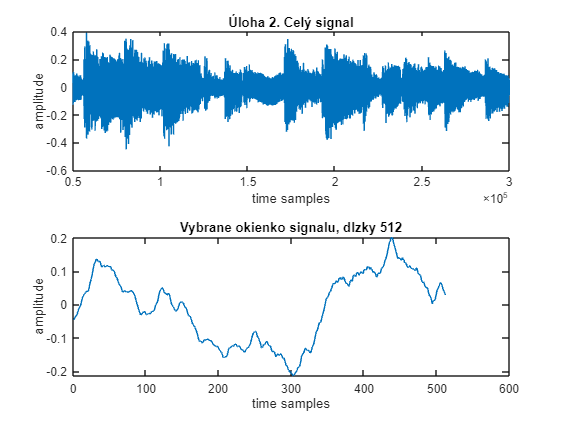

% Riesenie / Solution lossy reduction
% 1. Načítajte zvukovú stopu (napr. hudbu z dokumentového serveru) ako signál.
% ladicka = importdata("ladicka.wav")
fado = importdata("Fado1.wav");
fs = fado.fs;
rawSignal = fado.data(:,1);
rawSignal = rawSignal';
figure
% 2. Vizualizujte signál (celý aj detail okienka použitého v bode 3).
    figure
        tiledlayout(2,1)
        nexttile
        plot(rawSignal)
        xlim([0.5*100000 3*100000])
        title('Úloha 2. Celý signal')
        xlabel("time samples")
        ylabel("amplitude")
        choosenSignal512 = rawSignal(65001:65512);
        nexttile
        plot(choosenSignal512)
        title('Vybrane okienko signalu, dlzky 512')
        xlabel("time samples")
        ylabel("amplitude")

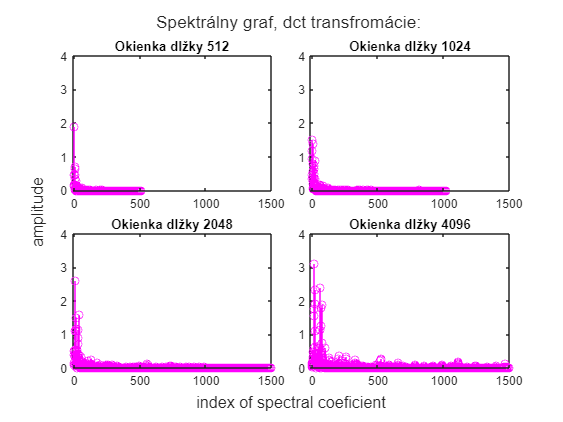

% 3. Spočítajte kosínovú transformáciu (dct) aspoň pre jedno okienko a vizualizujte spektrum okienka (použite funkciu matlabu stem).
    choosenSignal1024 = rawSignal(65001:66024);
    choosenSignal2048 = rawSignal(65001:67048);
    choosenSignal4096 = rawSignal(65001:69096);
    % Okienko velkosti 512
    figure
        tcl = tiledlayout(2,2,"TileSpacing","compact");
            dct512 = dct(choosenSignal512);
            nexttile
            stem(abs(dct512), Color="magenta")
            title('Okienka dlžky 512')
            ylim([0 4])
            xlim([-10 1500])   %limity zadané pre lepsie porovnávanie, s tým že kladná, krajná hodnota bola zvolená ako kompromis, a tiež že za nou neboli pozorované zmeny v priebehu grafu
        % Okienko velkosti 1024
            dct1024 = dct(choosenSignal1024);
            nexttile
            stem(abs(dct1024), Color="magenta")
            title('Okienka dlžky 1024')
            ylim([0 4])
            xlim([-10 1500])
         % Okienko velkosti 2048
            dct2048 = dct(choosenSignal2048);
            nexttile
            stem(abs(dct2048), Color="magenta")
            title('Okienka dlžky 2048')
            ylim([0 4])
            xlim([-10 1500])
          % Okienko velkosti 4096
            dct4096 = dct(choosenSignal4096);
            nexttile
            stem(abs(dct4096), Color="magenta")
            title('Okienka dlžky 4096')
            ylim([0 4])
            xlim([-10 1500])
        title(tcl, 'Spektrálny graf, dct transfromácie: ')
        xlabel(tcl, "index of spectral coeficient")
        ylabel(tcl, "amplitude")

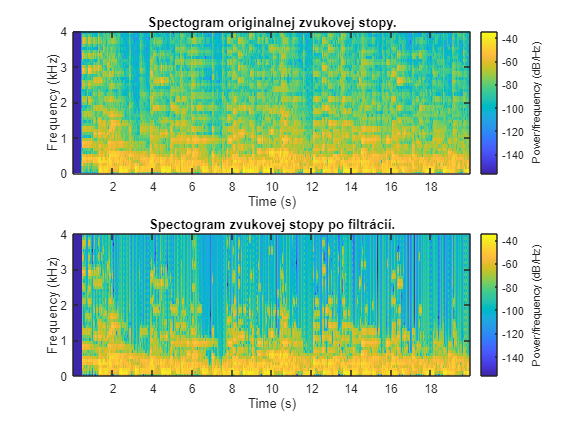


% 4. Za pomoci cyklu for prejdite celým signálom tak, že vyberiete okienka bez prekryvu.
    %5.  ----> zbytok časti k 5. je na konci vo funkcí
    [wholeOriginDCT, wholeDCT, wholeIDCT] = cycleWidnowDCTReduction(rawSignal, 0.09, 512);
% 6. Vizualizujte spektrum signálu pred a po filtrácií formou spektrogramu.
figure
    tiledlayout(2,1,"TileSpacing","compact");
    nexttile
        spectrogram(rawSignal, hamming(512), 256, 512, fs, "yaxis")
        title("Spectogram originalnej zvukovej stopy.")
        ylim([0 4])
    nexttile
        spectrogram(wholeIDCT, hamming(512), 256, 512, fs, "yaxis")
         title("Spectogram zvukovej stopy po filtrácií.")
         ylim([0 4])

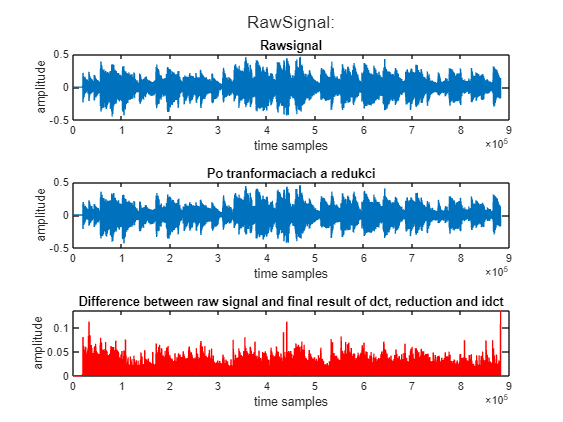

figure
trl2 = tiledlayout(3,1);
    nexttile
        plot(rawSignal)
        title('Rawsignal')
        xlabel("time samples")
        ylabel("amplitude")
    nexttile
        plot(wholeIDCT)
        title('Po tranformaciach a redukci')
        xlabel("time samples")
        ylabel("amplitude")
    nexttile
        plot(rawSignal - wholeIDCT, Color="red")
        title('Difference between raw signal and final result of dct, reduction and idct')
        xlabel("time samples")
        ylabel("amplitude")
    title(trl2, "RawSignal:")


% Vypočujte si výstupný, filtrovaný signál s rôznymi prahmi nulovania spektrálnych koeficientov.
            [wholeOriginDCT_1, wholeDCT_1, wholeIDCT_1] = cycleWidnowDCTReduction(rawSignal, 0.01, 512);
            [wholeOriginDCT_2, wholeDCT_2, wholeIDCT_2] = cycleWidnowDCTReduction(rawSignal, 0.03, 512);
            [wholeOriginDCT_3, wholeDCT_3, wholeIDCT_3] = cycleWidnowDCTReduction(rawSignal, 0.06, 512);
            [wholeOriginDCT_4, wholeDCT_4, wholeIDCT_4] = cycleWidnowDCTReduction(rawSignal, 0.09, 512);
            [wholeOriginDCT_5, wholeDCT_5, wholeIDCT_5] = cycleWidnowDCTReduction(rawSignal, 0.12, 512);
            [wholeOriginDCT_6, wholeDCT_6, wholeIDCT_6] = cycleWidnowDCTReduction(rawSignal, 0.3, 512);
            [wholeOriginDCT_7, wholeDCT_7, wholeIDCT_7] = cycleWidnowDCTReduction(rawSignal, 0.6, 512);
            [wholeOriginDCT_8, wholeDCT_8, wholeIDCT_8] = cycleWidnowDCTReduction(rawSignal, 0.9, 512);
            audio0 = audioplayer(rawSignal, fs);
            audio1 = audioplayer(wholeIDCT_1, fs);
            audio2 = audioplayer(wholeIDCT_2, fs);
            audio3 = audioplayer(wholeIDCT_3, fs);
            audio4 = audioplayer(wholeIDCT_4, fs);
            audio5 = audioplayer(wholeIDCT_5, fs);
            audio6 = audioplayer(wholeIDCT_6, fs);
            audio7 = audioplayer(wholeIDCT_7, fs);
            audio8 = audioplayer(wholeIDCT_8, fs);
            playblocking(audio0,  [1,fs*3])
            playblocking(audio1,  [1,fs*3])
            playblocking(audio2,  [1,fs*3])  %<-zaznamenatelné minimálny šum, a mierny tlm
            playblocking(audio3,  [1,fs*3])  %<--zaznamenatelné malý šum, a mierny tlm
            playblocking(audio4,  [1,fs*3])  %<---tlmený po celej dĺžke a mierny šum
            playblocking(audio5,  [1,fs*3])  %<----výraznejší šum a tlm
            playblocking(audio6,  [1,fs*3])  %<-----zretelne počutelný šum a zvuk e tlmený ako pod vodnou hladinou
            playblocking(audio7,  [1,fs*3])  %<------obtiaťne zrozumitelný zvuk
            playblocking(audio8,  [1,fs*3])  %<-------iba niektoré časti boly podobné pôvodnemu
% Porovnajte. Pri akej hodnote prahu došlo k značnému znehodnoteniu kvality zvukovej stopy?
% Od 0.09 tresholdu, došlo k značnej zmene kvality zvukovej stopy, pričom pri tresholde blížiacej sa 1 zvukova stopa bola iba čiastočne rozpoznávatelná. 

function [wholeOriginDCT_out, wholeDCT_out, wholeIDCT_out] = cycleWidnowDCTReduction(rawSignalPar, tresholdPar, windowSizePar)
    M = round(length(rawSignalPar)/windowSizePar);
    if(M*windowSizePar > length(rawSignalPar))
        M = M - 1;
    end
    wholeOriginDCT_out = zeros(1,length(rawSignalPar));
    wholeDCT_out = zeros(1,length(rawSignalPar));
    wholeIDCT_out = zeros(1,length(rawSignalPar));
    for x = 1:(M)
        indexFrom = (x-1)*windowSizePar;
        indexTo = indexFrom+windowSizePar;
        windowX = rawSignalPar(1+indexFrom:indexTo); 
        % 5. Pre jednotlivé okienka vypočítajte dct, nastavte amplitúdy
        dctX = dct(windowX);
        wholeOriginDCT_out(1+indexFrom:indexTo) = dctX;
        %5.1 spektrálnych koeficientov, ktoré sú menšie ako zvolený prah (teda všetko, čo má menšiu amplitúdu ako zvolený prah) na hodnotu 0
        %[Min, ~] = min(abs(dctX));
        %treshlod = Min;
        indx = (abs(dctX) < tresholdPar);
        dctX(indx) = 0;
        wholeDCT_out(1+indexFrom:indexTo) = dctX;
        %5.2 vypočítajte spätnú kosínovú transformáciu (idct). Takto získate nový, filtrovaný signál.
        idctX = idct(dctX);
        wholeIDCT_out(1+indexFrom:indexTo) = idctX;
    end
end
